# One-Dimensional Gaussian Process

## Define the hyperparameters

l = 50;
VarSignal = 0;
VarNoise = 100;

## Create joint prior of the training and test points

% select test points (ti, unknown fi)
MINt = 0; MAXt = 10;
t = (MINt : 0.1 : MAXt)';

% assign training points (tSTARi, fSTARi)
Npoints = 5;
tSTAR = sortrows( ( MINt + (MAXt-MINt) .* rand(1,Npoints) )' );
fSTAR = ( 2 + (3-2) .* rand(1,Npoints) )';

## Calculate prior

% calculate the covariance matrix of the test points (squared exponential kernel)
Ktt = exp(-1/2 * ( meshgrid(t,ones(1,numel(t)))-meshgrid(t,ones(1,numel(t)))' ).^2);

% calculate the covariance matrix of the training points
KtSTARtSTAR = exp(-1/2 * ( meshgrid(tSTAR,ones(1,numel(tSTAR)))-meshgrid(tSTAR,ones(1,numel(tSTAR)))' ).^2);

% calculate the covariance matrix of the training vs test points
KtSTARt = exp(-1/2 * ( meshgrid(tSTAR,ones(1,numel(t)))'-meshgrid(t,ones(1,numel(tSTAR))) ).^2);

% calculate the covariance matrix of the test vs training points
KttSTAR = exp(-1/2 * ( meshgrid(t,ones(1,numel(tSTAR)))'-meshgrid(tSTAR,ones(1,numel(t))) ).^2);


% calculate the covariance matrix of the prior
SigmaPRIOR = [ Ktt , KttSTAR; KtSTARt , KtSTARtSTAR];

% fix the mean of the prior
MeanPRIOR = zeros(size(SigmaPRIOR,1),1);

% extract points from a multivariate gaussian
f1 = mvnrnd(MeanPRIOR,SigmaPRIOR)';
f2 = mvnrnd(MeanPRIOR,SigmaPRIOR)';
f3 = mvnrnd(MeanPRIOR,SigmaPRIOR)';


## Create posterior

% extract points using only the Ktt matrix (for the training)
f = mvnrnd(zeros(size(Ktt,1),1),Ktt)';

% assign the numerical correction factor (matrices close to singular)
factor = 0;

% calculate the mean vector and covariance matrix of the posterior
MeanPOSTERIOR = KttSTAR * ( KtSTARtSTAR + factor * eye(size(KtSTARtSTAR,1)) )^-1 * fSTAR;
SigmaPOSTERIOR= Ktt - KttSTAR * ( KtSTARtSTAR + factor * eye(size(KtSTARtSTAR,1)) )^-1 * KtSTARt;

% extract from the posterior
f1post = mvnrnd(MeanPOSTERIOR,SigmaPOSTERIOR )';
f2post = mvnrnd(MeanPOSTERIOR,SigmaPOSTERIOR )';
f3post = mvnrnd(MeanPOSTERIOR,SigmaPOSTERIOR )';

## Plot

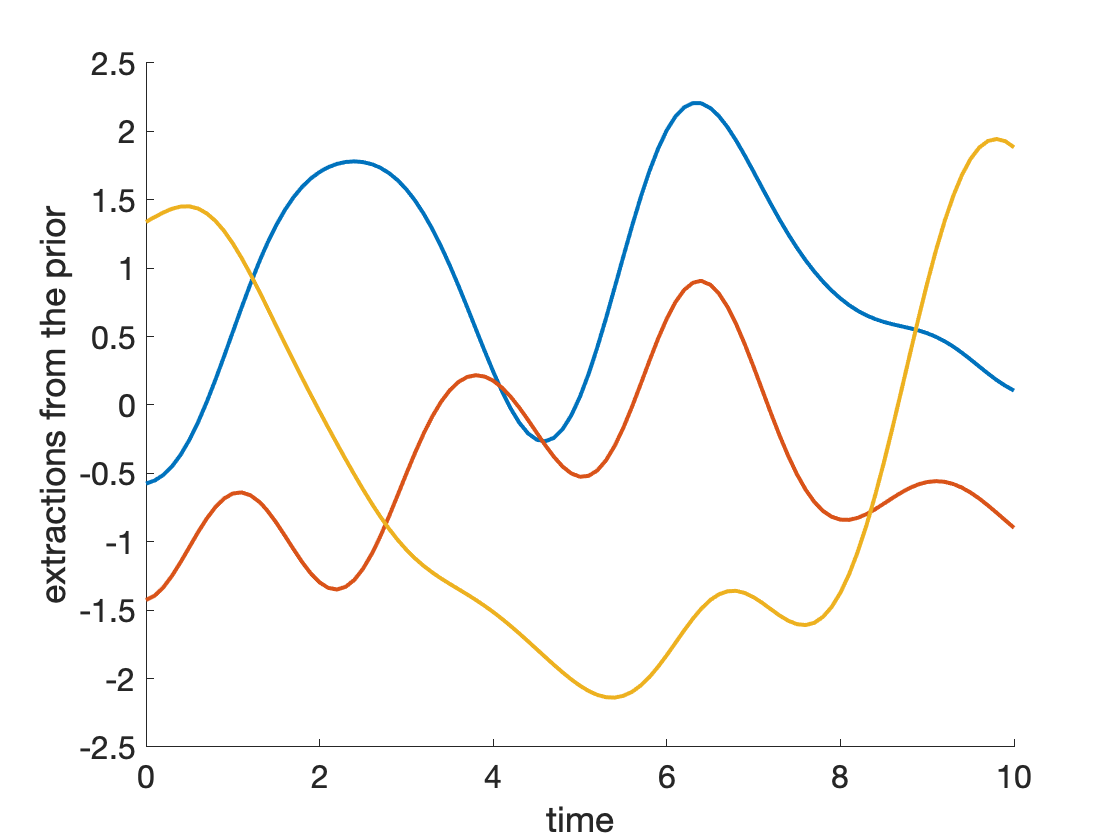

[tPLOT,id] = sortrows([t; tSTAR]);

figure
hold on

plot(tPLOT, f1(id), 'LineWidth', 2)
plot(tPLOT, f2(id), 'LineWidth', 2)
plot(tPLOT, f3(id), 'LineWidth', 2)

xlabel('time')
ylabel('extractions from the prior')
set(gca, 'FontSize', 16)

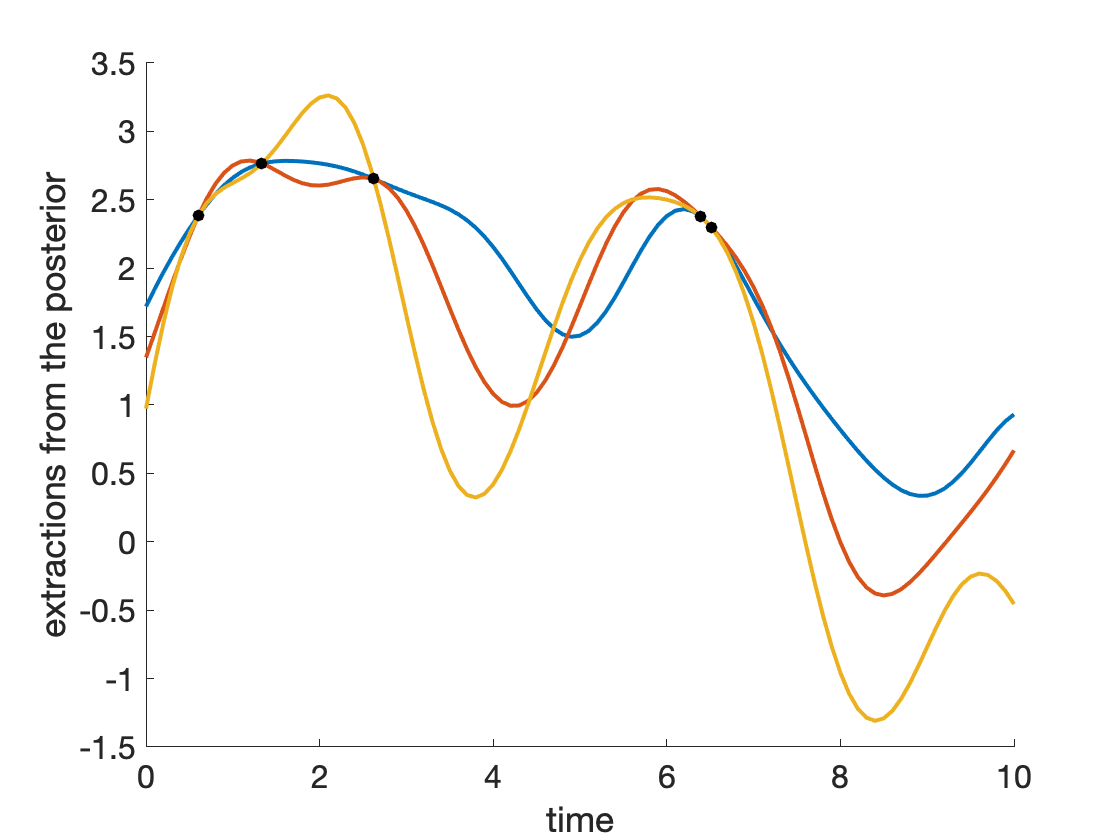



figure
hold on

plot(t, f1post, 'LineWidth', 2)
plot(t, f2post, 'LineWidth', 2)
plot(t, f3post, 'LineWidth', 2)
scatter(tSTAR, fSTAR, 36, 'black', 'filled')

xlabel('time')
ylabel('extractions from the posterior')
set(gca, 'FontSize', 16)

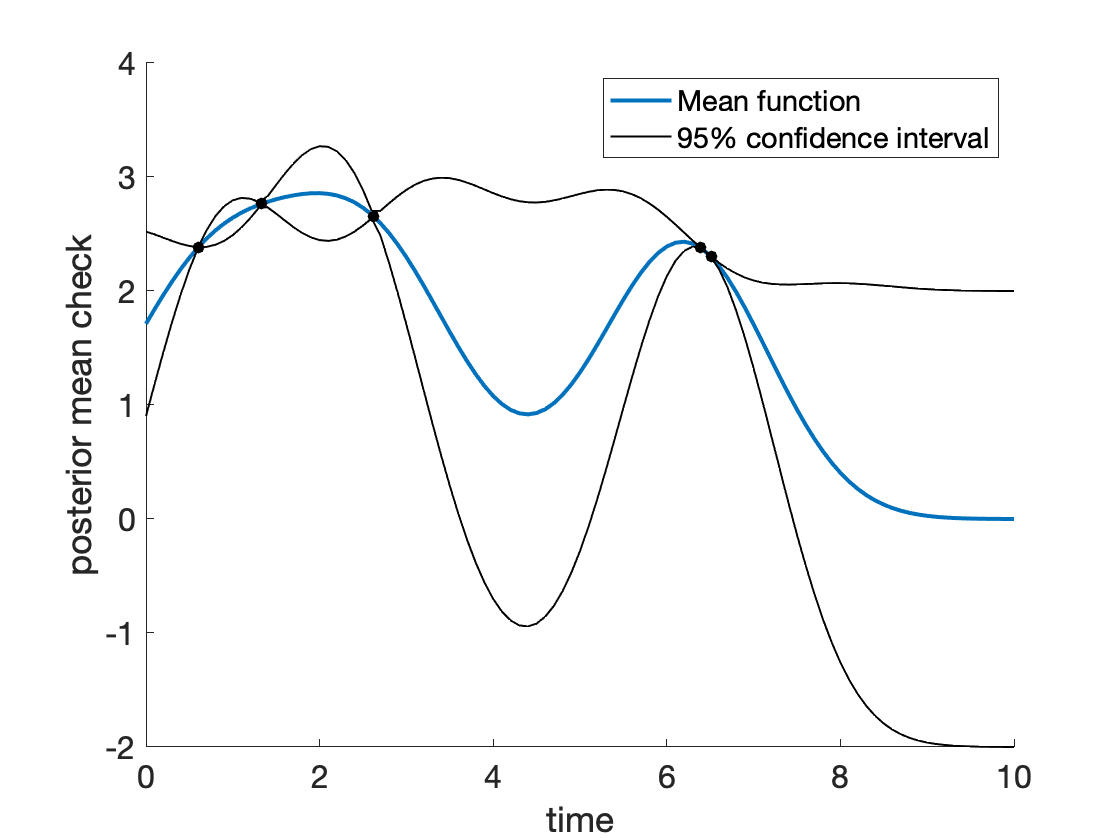


figure
hold on
plot(t, MeanPOSTERIOR, 'LineWidth', 2)
plot(t, MeanPOSTERIOR + 2*diag(SigmaPOSTERIOR).^0.5, 'k', 'LineWidth', 1)
plot(t, MeanPOSTERIOR - 2*diag(SigmaPOSTERIOR).^0.5, 'k', 'LineWidth', 1)
scatter(tSTAR, fSTAR, 36, 'black', 'filled')
legend('Mean function', '95% confidence interval')

xlabel('time')
ylabel('posterior mean check')
set(gca, 'FontSize', 16)